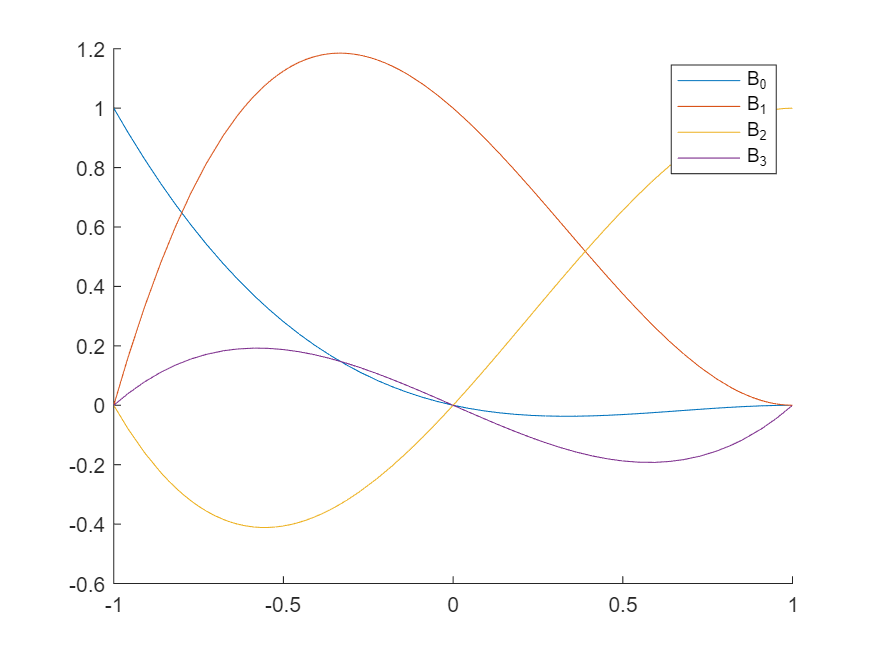

clear; 

syms h hm1 u t um1 u0 u1 f0 f1

% b0 = getPoly(t, h, hm1, [1,0,0]');
% b1 = getPoly(t, h, hm1, [0,1,0]');
% b2 = getPoly(t, h, hm1, [0,0,1]');
% b3(t) = 0 * t;

b0 = getPolyV2(t, h, hm1, [1,0,0,0]');
b1 = getPolyV2(t, h, hm1, [0,1,0,0]');
b2 = getPolyV2(t, h, hm1, [0,0,1,0]');
b3 = getPolyV2(t, h, hm1, [0,0,0,1]');

figure(1); clf;hold on;
fplot(subs(b0,[h,hm1],[1,1]),[-1,1])
fplot(subs(b1,[h,hm1],[1,1]),[-1,1])
fplot(subs(b2,[h,hm1],[1,1]),[-1,1])
fplot(subs(b3,[h,hm1],[1,1]),[-1,1])
hold off;
legend('B_0','B_1','B_2','B_3');

## integration

syms alpha alpha2 v0 v1 v2
bases(t) = [1,t,t^2];
bases2(t) = [1,t,t^2,t^3]; % _2 is for 3rd degree poly integration
weights = int(bases / ([bases(0);bases(alpha); bases(1)]),t,0,1)

$$weights = \left(\begin{array}{ccc} \frac{1}{2}-\frac{1}{6\,\alpha } & -\frac{1}{6\,\alpha \,\left(\alpha -1\right)} & \frac{1}{6\,\left(\alpha -1\right)}+\frac{1}{2} \end{array}\right)$$

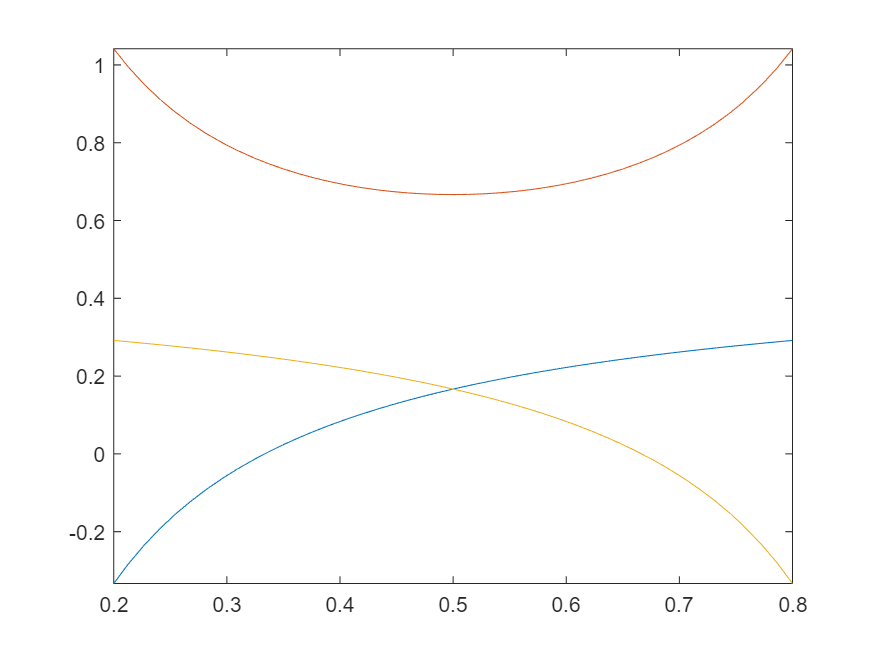

fplot(weights, [0.2,0.8])

weights2 = int(bases2 / ([bases2(0);bases2(alpha);bases2(alpha2); bases2(1)]),t,0,1)

$$weights2 = \begin{array}{l} \left(\begin{array}{cccc} \frac{\frac{\alpha }{2}-\frac{1}{6}}{\alpha }-\frac{\sigma_{1}}{\alpha \,\alpha_{2}} & \frac{2\,\alpha_{2}-1}{12\,\alpha \,\left(\alpha -\alpha_{2}\right)\,\left(\alpha -1\right)} & -\frac{2\,\alpha -1}{12\,\alpha_{2}\,\left(\alpha -\alpha_{2}\right)\,\left(\alpha_{2}-1\right)} & \frac{\frac{\alpha }{2}-\frac{1}{3}}{\alpha -1}+\frac{\sigma_{1}}{\left(\alpha -1\right)\,\left(\alpha_{2}-1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\alpha }{6}-\frac{1}{12} \end{array}$$

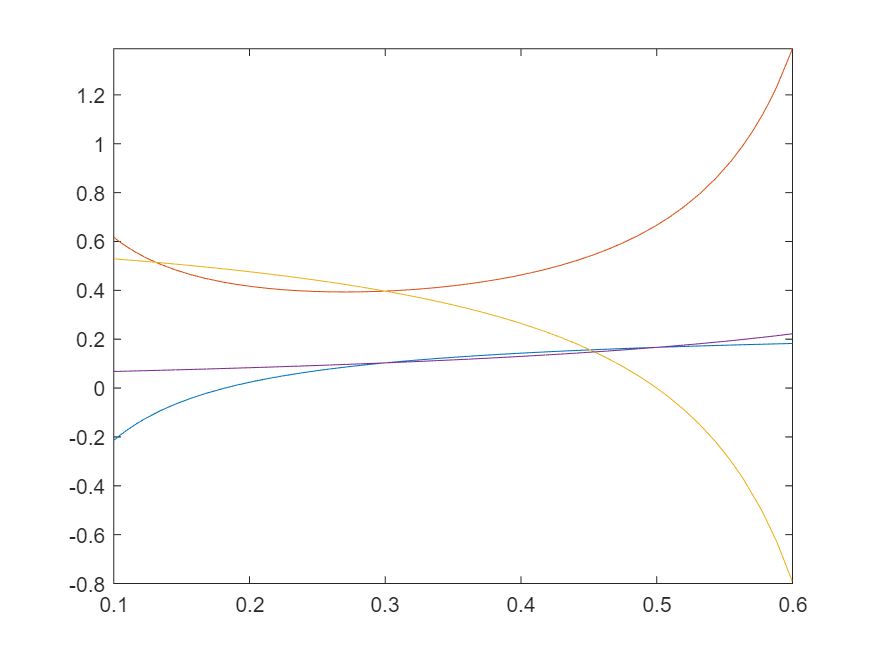

fplot(subs(weights2,alpha2,0.7), [0.1,0.6])


db0 = diff(b0, t);
db1 = diff(b1, t);
db2 = diff(b2, t);
db3 = diff(b3, t);
dbs = [db0(alpha * h), db1(alpha * h), db2(alpha * h), db3(alpha * h)];


% For simplified integration scheme
int01 = (weights(1) * f0 + weights(3) * f1 + weights(2) * dbs * [um1; u0; u1; f1])*h;
int01R = int01 - (u1 - u0);

int01R1 = simplify(expand(subs(int01R, hm1, h)))

$$int01R1 = \frac{\left(3\,\alpha -1\right)\,\left(4\,u_{0}-5\,u_{1}+{\mathrm{um}}_{1}+4\,f_{0}\,h+2\,f_{1}\,h\right)}{24\,\alpha }$$

ind01R1c = int01R1*24*alpha/(3*alpha-1)

$$ind01R1c = 4\,u_{0}-5\,u_{1}+{\mathrm{um}}_{1}+4\,f_{0}\,h+2\,f_{1}\,h$$

syms uf(t)
tuf(t) = taylor(uf(t), t, 0, "Order", 10);
dtuf(t) = diff(tuf(t),t)

$$dtuf(t) = \frac{{\mathrm{uf}}^{\left(9\right)}\left(0\right)\,t^{8}}{40320}+\frac{{\mathrm{uf}}^{\left(8\right)}\left(0\right)\,t^{7}}{5040}+\frac{{\mathrm{uf}}^{\left(7\right)}\left(0\right)\,t^{6}}{720}+\frac{{\mathrm{uf}}^{\left(6\right)}\left(0\right)\,t^{5}}{120}+\frac{{\mathrm{uf}}^{\left(5\right)}\left(0\right)\,t^{4}}{24}+\frac{{\mathrm{uf}}^{\left(4\right)}\left(0\right)\,t^{3}}{6}+\frac{{\mathrm{uf}}^{\prime \prime \prime }\left(0\right)\,t^{2}}{2}+{\mathrm{uf}}^{\prime \prime }\left(0\right)\,t+{\mathrm{uf}}^{\prime }\left(0\right)$$

expand(subs(ind01R1c, [um1, u0, u1,f0,f1], [tuf(-h), tuf(0), tuf(h), dtuf(0), dtuf(h)]))

$$ans = \frac{{\mathrm{uf}}^{\left(9\right)}\left(0\right)\,h^{9}}{30240}+\frac{{\mathrm{uf}}^{\left(8\right)}\left(0\right)\,h^{8}}{3360}+\frac{{\mathrm{uf}}^{\left(7\right)}\left(0\right)\,h^{7}}{630}+\frac{{\mathrm{uf}}^{\left(6\right)}\left(0\right)\,h^{6}}{90}+\frac{{\mathrm{uf}}^{\left(5\right)}\left(0\right)\,h^{5}}{30}+\frac{{\mathrm{uf}}^{\left(4\right)}\left(0\right)\,h^{4}}{6}$$

syms G lambda kappa
% assume(G, "positive")
ind01R1c_kG =  expand(G*subs(ind01R1c, [um1, u1, f0, f1], [u0/G, u0*G, u0 * kappa/h, u0 * kappa/h]))

$$ind01R1c\_kG = u_{0}+4\,G\,u_{0}-5\,G^{2}\,u_{0}+6\,G\,\kappa \,u_{0}$$

sol = solve(ind01R1c_kG, G, "ReturnConditions",true)

sol = struct with fields:
             G: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


sol.conditions

$$ans = \left(\begin{array}{c} \mathrm{symtrue}\\ \mathrm{symtrue} \end{array}\right)$$

sol.G

$$ans = \left(\begin{array}{c} \frac{3\,\kappa }{5}-\frac{\sqrt{3}\,\sqrt{3\,\kappa^{2}+4\,\kappa +3}}{5}+\frac{2}{5}\\ \frac{3\,\kappa }{5}+\frac{\sqrt{3}\,\sqrt{3\,\kappa^{2}+4\,\kappa +3}}{5}+\frac{2}{5} \end{array}\right)$$

fG1 = matlabFunction(symfun(sol.G(1), kappa));
fG2 = matlabFunction(symfun(sol.G(2), kappa));
fGG = @(kappa) max(abs(fG1(kappa)), abs(fG2(kappa)));
sol1 = solve(ind01R1c_kG, kappa, "ReturnConditions",true)

sol1 = struct with fields:
         kappa: -(- 5*G^2 + 4*G + 1)/(6*G)
    parameters: [1×0 sym]
    conditions: G ~= 0 & u0 ~= 0


fFF = matlabFunction(symfun(sol1.kappa, G))

fFF = function_handle with value:
    @(G)((G.*4.0-G.^2.*5.0+1.0).*(-1.0./6.0))./G


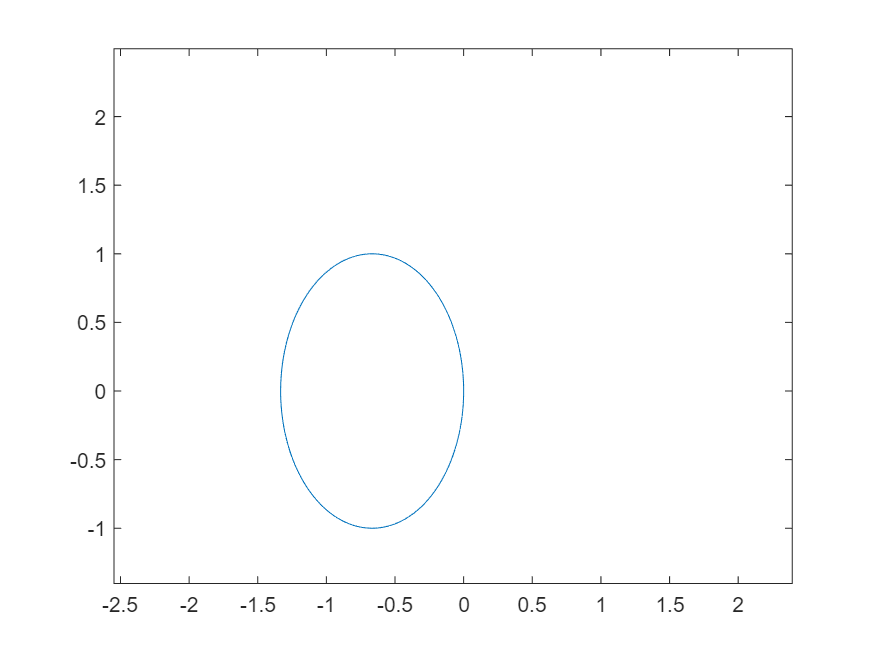

Gs = exp(1i * pi * linspace(0,2,201));
FFs = fFF(Gs);
plot(FFs); axis equal;



limit(sol.G, kappa, inf)

$$ans = \left(\begin{array}{c} 0\\ \infty \end{array}\right)$$

## input

% for use:
coefsN = simplify(expand([b0(alpha*h), b1(alpha*h), b2(alpha*h), b3(alpha*h)]))

$$coefsN = \left(\begin{array}{cccc} -\frac{\alpha \,h^{3}\,{\left(\alpha -1\right)}^{2}}{{\mathrm{hm}}_{1}\,{\left(h+{\mathrm{hm}}_{1}\right)}^{2}} & \frac{{\left(\alpha -1\right)}^{2}\,\left({\mathrm{hm}}_{1}+\alpha \,h\right)}{{\mathrm{hm}}_{1}} & \frac{\alpha \,\left(-2\,\alpha^{2}\,h^{2}-\alpha^{2}\,h\,{\mathrm{hm}}_{1}+3\,\alpha \,h^{2}-\alpha \,{{\mathrm{hm}}_{1}}^{2}+3\,h\,{\mathrm{hm}}_{1}+2\,{{\mathrm{hm}}_{1}}^{2}\right)}{{\left(h+{\mathrm{hm}}_{1}\right)}^{2}} & \frac{\alpha \,h\,\left(\alpha -1\right)\,\left({\mathrm{hm}}_{1}+\alpha \,h\right)}{h+{\mathrm{hm}}_{1}} \end{array}\right)$$


u_mid = coefsN * transpose([um1,u0,u1, f1])

$$u\_mid = \frac{\alpha \,u_{1}\,\left(-2\,\alpha^{2}\,h^{2}-\alpha^{2}\,h\,{\mathrm{hm}}_{1}+3\,\alpha \,h^{2}-\alpha \,{{\mathrm{hm}}_{1}}^{2}+3\,h\,{\mathrm{hm}}_{1}+2\,{{\mathrm{hm}}_{1}}^{2}\right)}{{\left(h+{\mathrm{hm}}_{1}\right)}^{2}}+\frac{u_{0}\,{\left(\alpha -1\right)}^{2}\,\left({\mathrm{hm}}_{1}+\alpha \,h\right)}{{\mathrm{hm}}_{1}}-\frac{\alpha \,h^{3}\,{\mathrm{um}}_{1}\,{\left(\alpha -1\right)}^{2}}{{\mathrm{hm}}_{1}\,{\left(h+{\mathrm{hm}}_{1}\right)}^{2}}+\frac{\alpha \,f_{1}\,h\,\left(\alpha -1\right)\,\left({\mathrm{hm}}_{1}+\alpha \,h\right)}{h+{\mathrm{hm}}_{1}}$$


syms f_mid; 
incre = weights * [f0; f_mid; f1] * h;

syms hR1;
cInter = simplify(subs(coefsN, hm1, hR1 * h));  
cInter(4) = cInter(4) / h

$$cInter = \left(\begin{array}{cccc} -\frac{\alpha \,{\left(\alpha -1\right)}^{2}}{{\mathrm{hR}}_{1}\,{\left({\mathrm{hR}}_{1}+1\right)}^{2}} & \frac{\left(\alpha +{\mathrm{hR}}_{1}\right)\,{\left(\alpha -1\right)}^{2}}{{\mathrm{hR}}_{1}} & \frac{\alpha \,\left(-\alpha^{2}\,{\mathrm{hR}}_{1}-2\,\alpha^{2}-\alpha \,{{\mathrm{hR}}_{1}}^{2}+3\,\alpha +2\,{{\mathrm{hR}}_{1}}^{2}+3\,{\mathrm{hR}}_{1}\right)}{{\left({\mathrm{hR}}_{1}+1\right)}^{2}} & \frac{\alpha \,\left(\alpha +{\mathrm{hR}}_{1}\right)\,\left(\alpha -1\right)}{{\mathrm{hR}}_{1}+1} \end{array}\right)$$

## linear stability

syms lambda kappa r_m1 G
incre_lam = simplify(subs(incre, [f0, f_mid, f1], lambda * [u0, u_mid, u1]));
incre_lam = simplify(subs(incre_lam, [f0, f_mid, f1], lambda * [u0, u_mid, u1]));

incre_lamG = simplify(subs(incre_lam, [um1, u1, h, hm1], [u0 / G, u0 * G, kappa/lambda, r_m1*kappa/lambda]))

$$incre\_lamG = \frac{\kappa \,u_{0}\,\left(G+\alpha -G\,\alpha +4\,G\,r_{\mathrm{m1}}+5\,G\,{r_{\mathrm{m1}}}^{2}+2\,G^{2}\,r_{\mathrm{m1}}+2\,G\,{r_{\mathrm{m1}}}^{3}+7\,G^{2}\,{r_{\mathrm{m1}}}^{2}+4\,G^{2}\,{r_{\mathrm{m1}}}^{3}+G^{2}\,\alpha \,{r_{\mathrm{m1}}}^{2}-G^{2}\,\kappa \,{r_{\mathrm{m1}}}^{2}-G^{2}\,\kappa \,{r_{\mathrm{m1}}}^{3}-2\,G\,\alpha \,r_{\mathrm{m1}}-G\,\alpha \,{r_{\mathrm{m1}}}^{2}+2\,G^{2}\,\alpha \,r_{\mathrm{m1}}-G^{2}\,\alpha \,\kappa \,r_{\mathrm{m1}}-G^{2}\,\alpha \,\kappa \,{r_{\mathrm{m1}}}^{2}-1\right)}{6\,G\,r_{\mathrm{m1}}\,{\left(r_{\mathrm{m1}}+1\right)}^{2}}$$

GG = simplify(expand((u0 + incre_lamG) / u0));
Gsol = solve(GG-G,G)


GsolR1 = subs(Gsol, r_m1, 1)

$$GsolR1 = \begin{array}{l} \left(\begin{array}{c} \frac{12\,\kappa -4\,\alpha \,\kappa -\sigma_{1}+24}{2\,\left(2\,\alpha \,\kappa^{2}-3\,\alpha \,\kappa -13\,\kappa +2\,\kappa^{2}+24\right)}\\ \frac{12\,\kappa -4\,\alpha \,\kappa +\sigma_{1}+24}{2\,\left(2\,\alpha \,\kappa^{2}-3\,\alpha \,\kappa -13\,\kappa +2\,\kappa^{2}+24\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{8\,\alpha^{2}\,\kappa^{3}+4\,\alpha^{2}\,\kappa^{2}-136\,\alpha \,\kappa^{2}-96\,\alpha \,\kappa -8\,\kappa^{3}+196\,\kappa^{2}+480\,\kappa +576} \end{array}$$

GsolR14 = simplify(subs(GsolR1, alpha, 1/2))

$$GsolR14 = \left(\begin{array}{c} \frac{10\,\kappa -\sqrt{-6\,\kappa^{3}+129\,\kappa^{2}+432\,\kappa +576}+24}{6\,\kappa^{2}-29\,\kappa +48}\\ \frac{10\,\kappa +\sqrt{-6\,\kappa^{3}+129\,\kappa^{2}+432\,\kappa +576}+24}{6\,\kappa^{2}-29\,\kappa +48} \end{array}\right)$$

infLim = limit(GsolR1, kappa, inf)

$$infLim = \left(\begin{array}{c} \left\{ \begin{array}{cl} \frac{\sqrt{336}}{20}-\frac{4}{5} & \text{ if }\alpha =-1\\ 0 & \text{ if }\alpha \neq -1 \end{array}\right.\\ \left\{ \begin{array}{cl} -\frac{\sqrt{336}}{20}-\frac{4}{5} & \text{ if }\alpha =-1\\ 0 & \text{ if }\alpha \neq -1 \end{array}\right. \end{array}\right)$$

FGsolR14 = matlabFunction(symfun( abs(GsolR14), kappa))

FGsolR14 = function_handle with value:
    @(kappa)[abs(kappa.*1.0e+1-sqrt(kappa.*4.32e+2+kappa.^2.*1.29e+2-kappa.^3.*6.0+5.76e+2)+2.4e+1)./abs(kappa.*-2.9e+1+kappa.^2.*6.0+4.8e+1);abs(kappa.*1.0e+1+sqrt(kappa.*4.32e+2+kappa.^2.*1.29e+2-kappa.^3.*6.0+5.76e+2)+2.4e+1)./abs(kappa.*-2.9e+1+kappa.^2.*6.0+4.8e+1)]


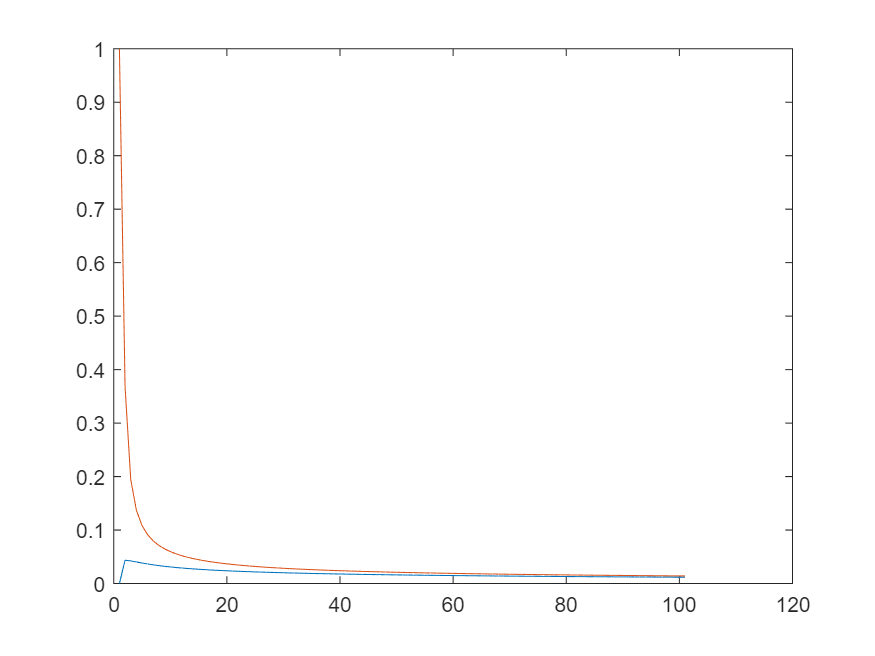

figure(2); clf;
plot(FGsolR14(1i * linspace(0,1000,101))')

## stablility region

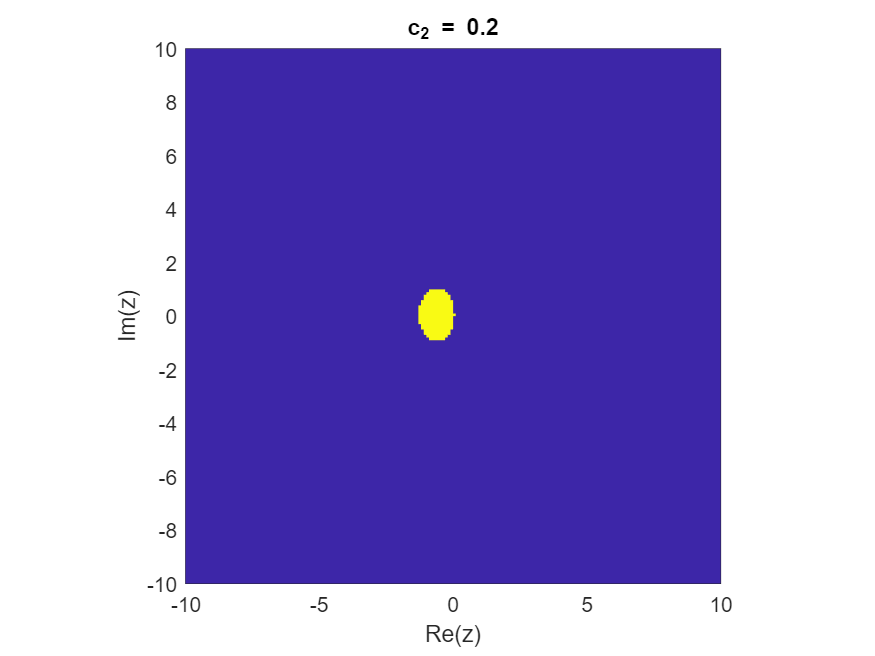

test_range = 10;
rSamp = linspace(-test_range,test_range,201);
iSamp = linspace(-test_range,test_range,201);
[rSampM,iSampM] = meshgrid(rSamp,iSamp);
zSampM = rSampM + 1i * iSampM;
Kf1 = matlabFunction(symfun(GsolR1(1), [kappa, alpha]));
Kf2 = matlabFunction(symfun(GsolR1(2), [kappa, alpha]));
alphatest = 0.2;
% KM = max(abs(Kf1(zSampM, alphatest)), abs(Kf2(zSampM, alphatest)));
KM = fGG(zSampM);
figure(1); clf; cla;
p = pcolor(rSampM,iSampM, double(KM < 1));
p.EdgeColor = 'none';
axis equal;
axis tight;
xlabel("Re(z)"); ylabel("Im(z)")
title(sprintf("c_2 = %.1g", alphatest))

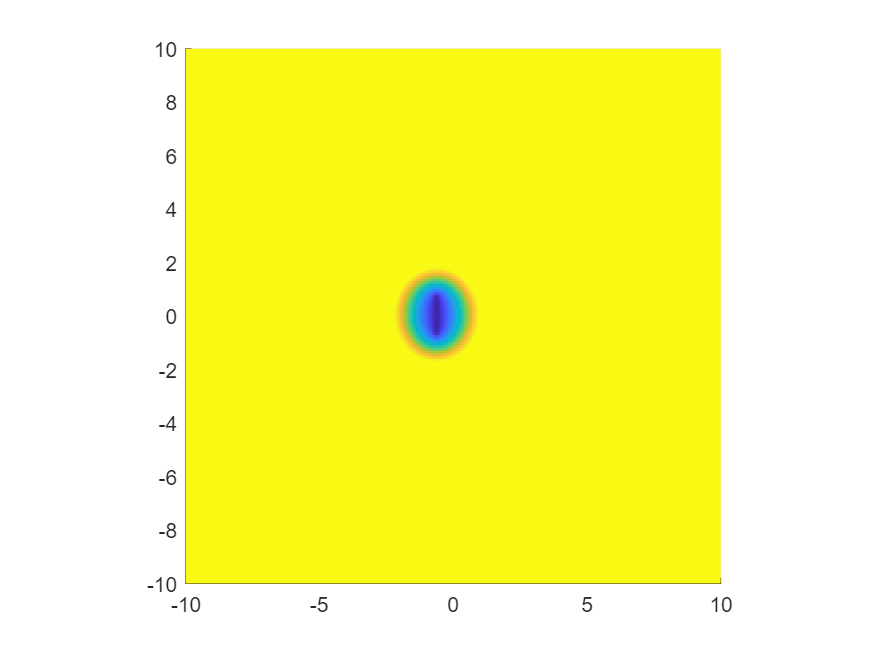



s = surf(rSampM,iSampM, double(min(KM,2)));
s.EdgeColor = 'none';
axis equal;
view(0,90)

## jacobian

## jacobian 2

syms J1 Jm h CFL
c = sym("c",[4,1]);
w = sym("w",[3,1]);
Jorig = [w(3) * J1 - 1/h, w(2) * Jm; c(3)/h + c(4)/h * J1, -1/h]

$$Jorig = \left(\begin{array}{cc} J_{1}\,w_{3}-\frac{1}{h} & \mathrm{Jm}\,w_{2}\\ \frac{c_{3}}{h}+\frac{J_{1}\,c_{4}}{h} & -\frac{1}{h} \end{array}\right)$$

syms theta
rowT = [1 0; theta, 1];
% rowT = inv([w(3), w(2); c(4), 0])
swapRow = [0,1;1,0];
Jtheta = swapRow * rowT * Jorig * swapRow';
Jtheta0 = simplify(expand(Jtheta))

$$Jtheta0 = \left(\begin{array}{cc} \mathrm{Jm}\,\theta \,w_{2}-\frac{1}{h} & \frac{c_{3}-\theta +J_{1}\,c_{4}+J_{1}\,h\,\theta \,w_{3}}{h}\\ \mathrm{Jm}\,w_{2} & J_{1}\,w_{3}-\frac{1}{h} \end{array}\right)$$

Jtheta = subs(Jtheta, [c;w], [transpose(coefsN); transpose(weights)]);
Jtheta = subs(Jtheta, hm1, h);
JthetaCh = subs(Jtheta, [J1,Jm], [-CFL/h, -CFL/h]) * h;
JthetaCh = simplify(expand(JthetaCh));
alphaSamp = 1/2;
% thetaSamp = -coefsN(4)/weights(3);
thetaSamp = 1;
% alphaSamp = alpha;
% thetaSamp = theta;
JJ = simplify(subs(JthetaCh,[theta,alpha],...
    [thetaSamp,alphaSamp]));
JJ = simplify(subs(JJ,[theta,alpha],...
    [thetaSamp,alphaSamp]));
rhoJJ = -JJ(2,1) * JJ(1,2) / JJ(2,2) / JJ(1,1)

$$rhoJJ = \frac{2\,\mathrm{CFL}\,\left(\frac{\mathrm{CFL}}{48}-\frac{11}{32}\right)}{3\,\left(\frac{2\,\mathrm{CFL}}{3}+1\right)\,\left(\frac{\mathrm{CFL}}{6}+1\right)}$$


simplify(limit(rhoJJ, CFL, inf))

$$ans = \frac{1}{8}$$

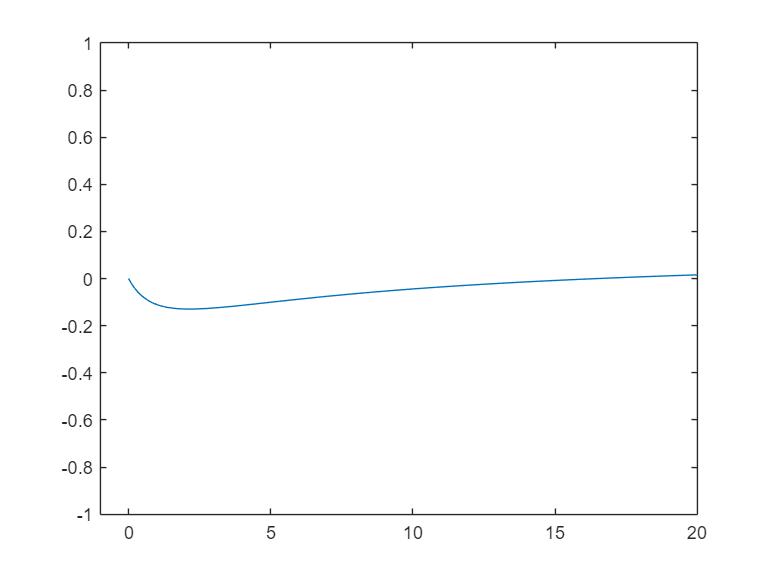


% thetaExtre = solve(diff(rhoJJ, CFL)==0, CFL)
% thetaExtreF = symfun(thetaExtre, theta);
% fplot(thetaExtreF)
% xlabel("\theta")

figure(2)
fplot(symfun((rhoJJ),CFL),[0,200])
xlim([-1,20])
ylim([-1,1])

## jacobian2 num find

figure(1); clf; hold on;
alphaSamps = [0.5,0.55,0.6];
lines = ["-o", "-x", "-d"]

lines = 1×3 string array
    "-o"    "-x"    "-d"


for  i = 1:3
    alphaSamp = alphaSamps(i);
% thetaSamp = -coefsN(4)/weights(3);
thetaSamp = theta;
JJ = simplify(subs(JthetaCh,[theta,alpha],...
    [thetaSamp,alphaSamp]));
JJ = simplify(subs(JJ,[theta,alpha],...
    [thetaSamp,alphaSamp]));
rhoJJ = -JJ(2,1) * JJ(1,2) / JJ(2,2) / JJ(1,1)
fRho = matlabFunction(symfun(abs(rhoJJ),[CFL, theta]));

CFLTestsR = [linspace(0,20,201), logspace(21,1e4,101)];
CFLTestsR(1) = 1e-3;
CFLTestsI = CFLTestsR;
% CFLTestsI = [CFLTestsI, -CFLTestsI];

CFLTests = CFLTestsR + 1i * CFLTestsI';
CFLTests = CFLTests(:)';

thetaTests = linspace(0,2,501);
rhoTests = fRho(CFLTests, thetaTests');
rhoMTests = max(rhoTests,[],2);
plot(thetaTests,rhoMTests, lines(i), "DisplayName", sprintf("$c_2 = %g$", alphaSamp), "MarkerIndices",1:20:numel(thetaTests));
ylim([0,2])
[minR, iminR] = min(rhoMTests,[],'all')
thetaM = thetaTests(iminR)
end

$$rhoJJ = \frac{2\,\mathrm{CFL}\,\left(\frac{3\,\mathrm{CFL}}{16}-\theta -\frac{\mathrm{CFL}\,\theta }{6}+\frac{21}{32}\right)}{3\,\left(\frac{\mathrm{CFL}}{6}+1\right)\,\left(\frac{2\,\mathrm{CFL}\,\theta }{3}+1\right)}$$

minR = 0.2491

iminR = 229

thetaM = 0.9120

$$rhoJJ = \frac{200\,\mathrm{CFL}\,\left(\frac{3069\,\mathrm{CFL}}{16000}-\theta -\frac{7\,\mathrm{CFL}\,\theta }{54}+\frac{22847}{32000}\right)}{297\,\left(\frac{7\,\mathrm{CFL}}{54}+1\right)\,\left(\frac{200\,\mathrm{CFL}\,\theta }{297}+1\right)}$$

minR = 0.3394

iminR = 281

thetaM = 1.1200

$$rhoJJ = \frac{25\,\mathrm{CFL}\,\left(\frac{24\,\mathrm{CFL}}{125}-\theta -\frac{\mathrm{CFL}\,\theta }{12}+\frac{96}{125}\right)}{36\,\left(\frac{\mathrm{CFL}}{12}+1\right)\,\left(\frac{25\,\mathrm{CFL}\,\theta }{36}+1\right)}$$

minR = 0.4956

iminR = 389

thetaM = 1.5520

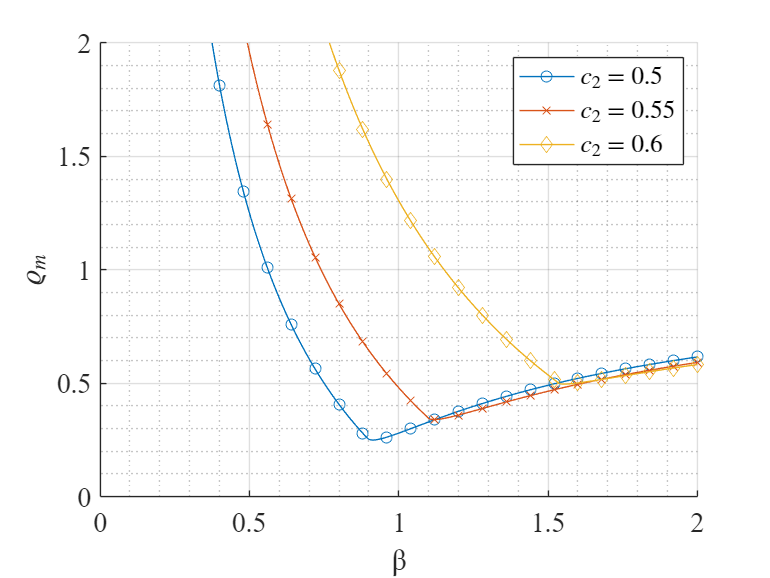

grid on ; grid minor;
legend("Interpreter","latex");
xlabel("\beta");
ylabel("$\varrho_m$","Interpreter","latex")
set(gca,"FontName","Times New Roman")
set(gca,"FontSize", 15)

## Jacobian 3

% factorization, gammaF(I + alphaF dt Jm) (I + betaF dt J1) + muF 
gammaF = -coefsN(2) * weights(3) / coefsN(4);
alphaF =  coefsN(4) * weights(2) / weights(3);
betaF =   coefsN(4) / coefsN(2);
muF = (coefsN(4) + coefsN(2) * weights(3))/coefsN(4);
syms TI JL;
FCT = (gammaF * TI *(1 + alphaF * JL) - muF)/ (gammaF * (1 + alphaF * JL)*(1 + betaF * JL + TI));
FCT = subs(subs(FCT, TI, -JL*1000),alpha,1/2)

$$FCT = \begin{array}{l} \frac{6\,h\,{\mathrm{hm}}_{1}\,\left(\frac{4\,\left(h+{\mathrm{hm}}_{1}\right)\,\left(\frac{\frac{h}{2}+{\mathrm{hm}}_{1}}{24\,{\mathrm{hm}}_{1}}-\frac{h\,\left(\frac{h}{2}+{\mathrm{hm}}_{1}\right)}{4\,\left(h+{\mathrm{hm}}_{1}\right)}\right)}{h\,\left(\frac{h}{2}+{\mathrm{hm}}_{1}\right)}+\frac{500\,\mathrm{JL}\,\left(h+{\mathrm{hm}}_{1}\right)\,\sigma_{1}}{3\,h\,{\mathrm{hm}}_{1}}\right)}{\left(h+{\mathrm{hm}}_{1}\right)\,\sigma_{1}\,\left(1000\,\mathrm{JL}+\frac{\mathrm{JL}\,h\,{\mathrm{hm}}_{1}}{h+{\mathrm{hm}}_{1}}-1\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{JL}\,h\,\left(\frac{h}{2}+{\mathrm{hm}}_{1}\right)}{h+{\mathrm{hm}}_{1}}-1 \end{array}$$

 fplot(symfun(FCT, JL))

Error using fplot>singleFplot
Input must be a function or functions of a single variable.

Error in fplot>@(f)singleFplot(cax,{f},limits,extraOpts,args) (line 200)
        hObj = cellfun(@(f) singleFplot(cax,{f},limits,extraOpts,args),fn{1},'UniformOutput',false);

Error in fplot>vectorizeFplot (

## Butcher

cbut = transpose([0,alpha,1])
bbut = weights
abut = [0,0,0; coefsN(3) + coefsN(2) * weights(1), coefsN(2) * weights(2), coefsN(4) + coefsN(2) * weights(3); bbut];
abut = simplify(expand(abut))
syms k 
fSimpC(k) = abut * cbut.^(k-1) - cbut.^k / k;
simplify(expand(fSimpC(4)))
predI = inv(abut(2:3,2:3))

function po = getPoly(t, h, hm1, cond)
    bases(t) = [1,t,t^2];
    dB(t) = diff(bases,t);
    valBases = [bases(-hm1); bases(0); bases(h);...
        ];
    coefs = valBases \ cond;
    po = bases * coefs;
end

function po = getPolyV2(t, h, hm1, cond)
    bases(t) = [1,t,t^2,t^3];
    dB(t) = diff(bases,t);
    valBases = [bases(-hm1); bases(0); bases(h);...
        dB(h)];
    coefs = valBases \ cond;
    po = bases * coefs;
end


